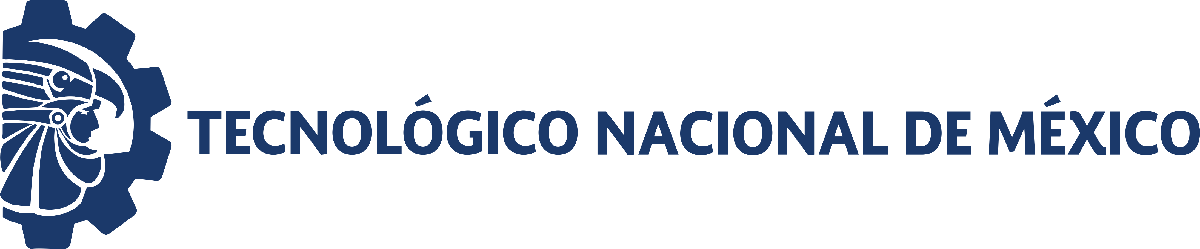                                 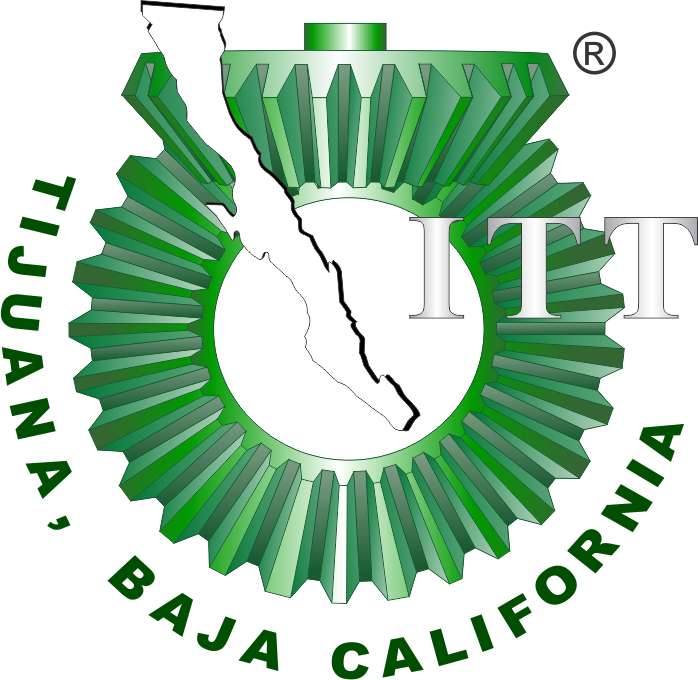

# Práctica 2: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                     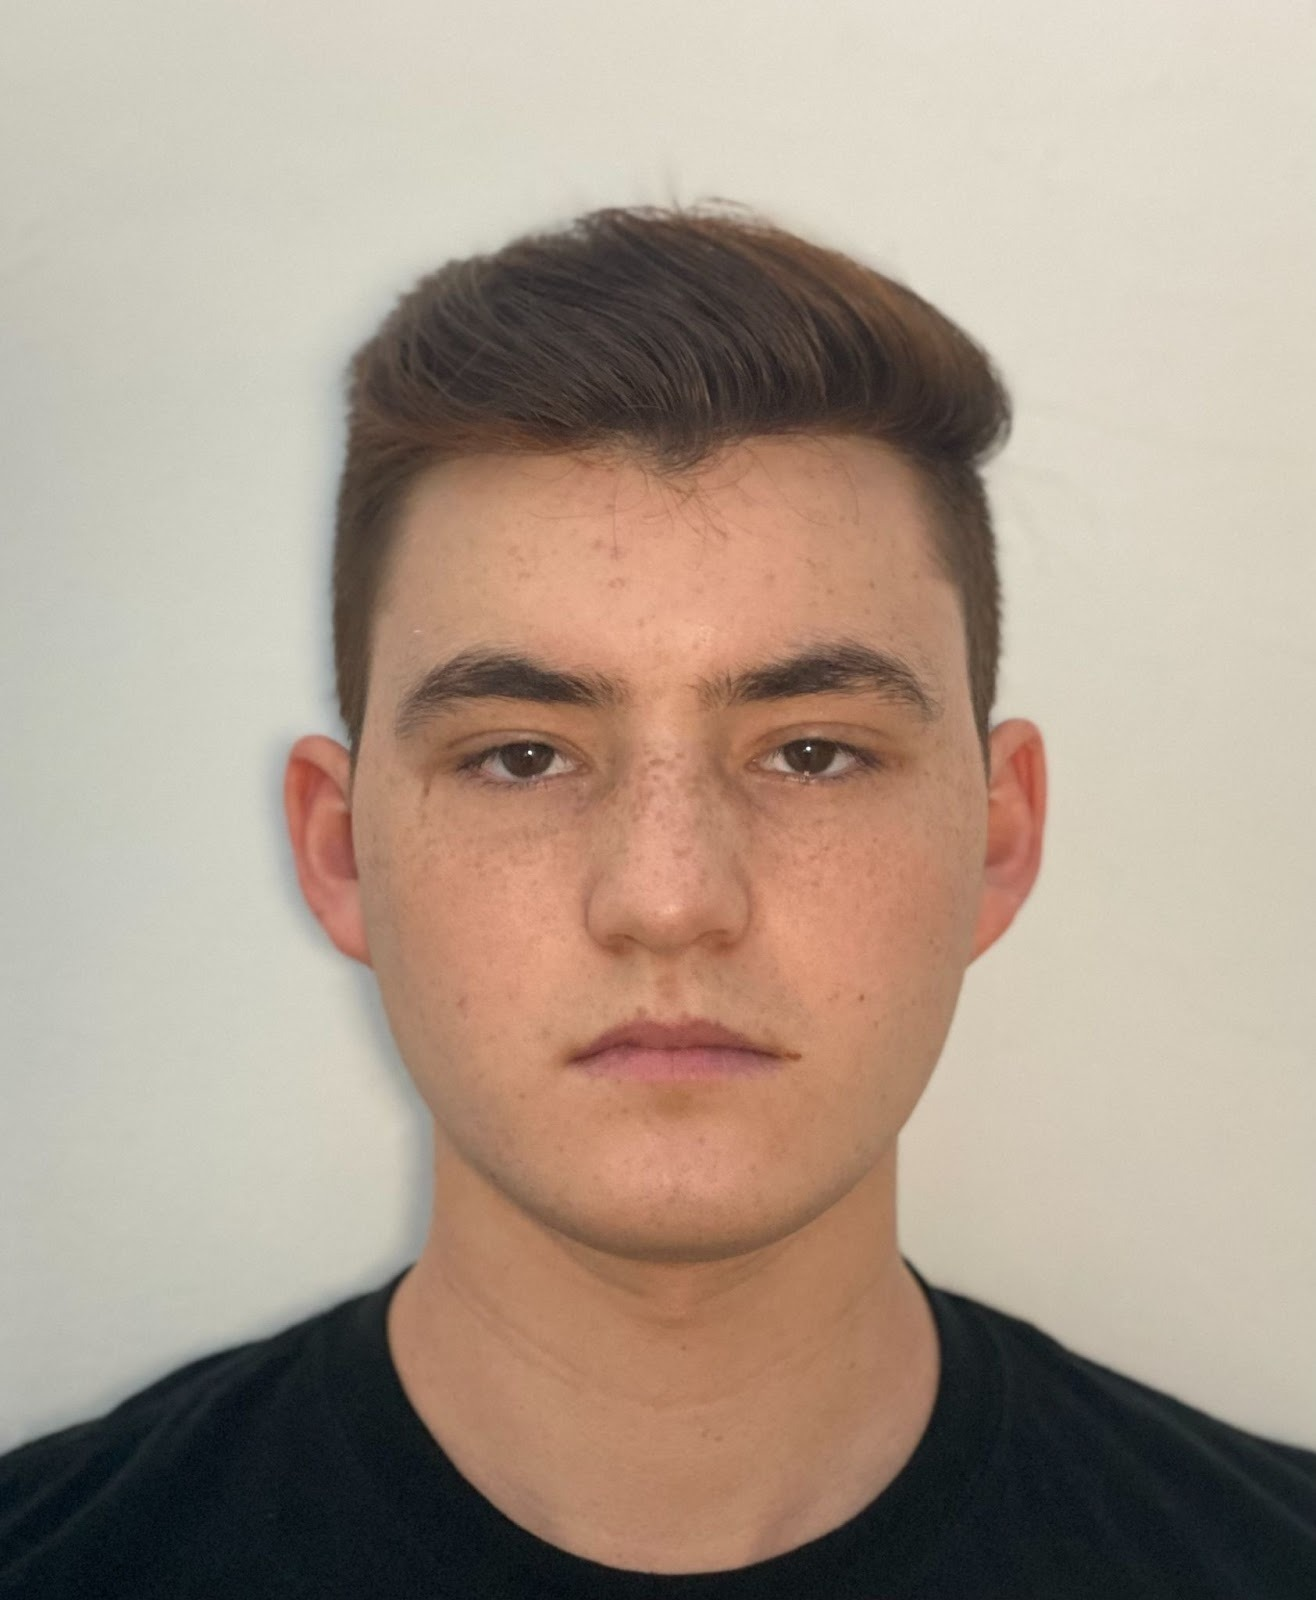

Nombre del alumno: Marco Antonio Campoy Alegria

Número de control: 21212145

Correo institucional: L21212145@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistemanew';
open_system(file);
parameter.StopTime = '15';
parameters.Solver = 'ode15s';
parameter.Maxstep = '1e-3';
x = sim(file,parameters);
writematrix(x.Pa, 'signal.xlsx');

## Respuesta del sistema

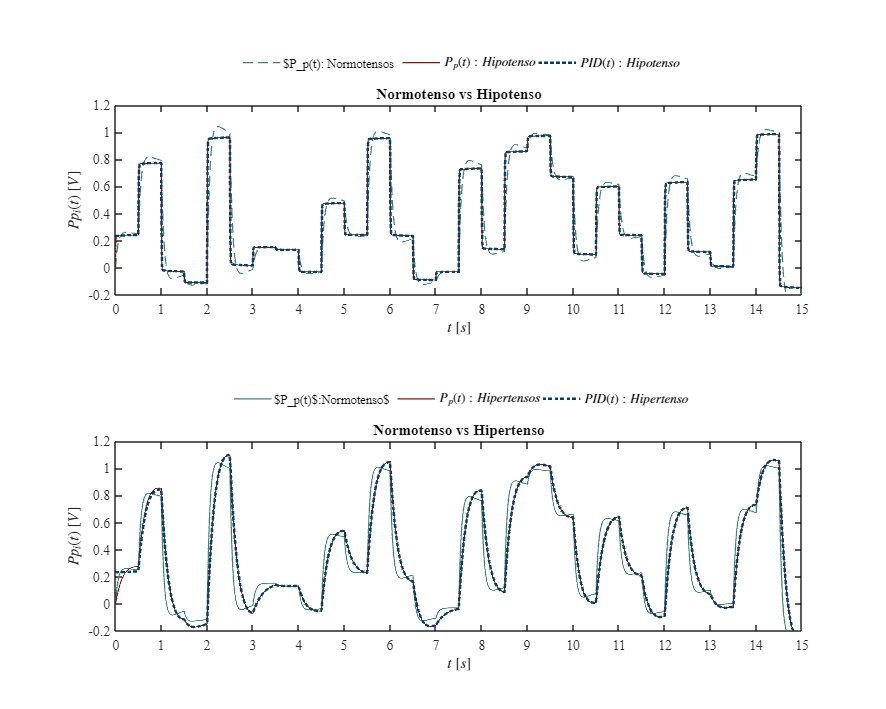

plotsignals(x.t,x.Pp1,x.Pp2,x.Pp3,x.PID1,x.PID2)

## Funcion de las señales

function plotsignals(t, Pp1, Pp2, Pp3, PID1, PID2)

set(figure(), 'Color', 'w')
set(gcf, 'units','centimeters','position',[1,1,25,20])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on, grid off; box on;
mycolors = [0.25, 0.51, 0.47;
            0.50, 0.10, 0.05;
            0.00, 0.25, 0.40];

colororder(mycolors)

subplot(2,1,1); box on; hold on;
P = plot(t, Pp1, '--', t, Pp2, '-', t, PID1, ':', 'LineWidth', 1); set(P(3), 'LineWidth', 2)
L = legend('$P_p(t): Normotensos','$P_p(t): Hipotenso$','$PID(t): Hipotenso$');
set(L, 'Interpreter', 'latex', ...
       'FontSize', 10, ...
       'Location', 'NorthOutside', ...
       'Orientation', 'horizontal', ...
       'Box', 'off');
xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$Pp_i(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)

xlim([0 ,15]); xticks(0:1:15);
ylim([-0.2 ,1.2]); yticks(-0.2:0.2:1.2);

T = title('Normotenso vs Hipotenso');
set(T, 'FontSize', 10);

set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

subplot(2,1,2); box on; hold on;


P = plot(t,Pp1,'-',t,Pp3,'-',t,PID2,':','LineWidth',1); set(P(3),'LineWidth',2)
L = legend('$P_p(t)$:Normotenso$', '$P_p(t):Hipertensos$', '$PID(t):Hipertenso$');
set(L,'Interpreter','Latex','FontSize',10,'Location','NorthOutside','Box','Off', ...
    'Orientation','Horizontal');

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
xlim([0,15]); xticks(0:1:15);
ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2);

T = title("Normotenso vs Hipertenso"); set(T,'FontSize',10);

set(gca,'FontName','Times New Roman','FontSize',11)

exportgraphics(gcf,'Cardiovascular.pdf','ContentType','vector')

end

     
